clear
close
format short

a)

z=0.12800+0.05825+0.03808

z = 0.2243

Slist = [   0 0 0 0
            0 1 1 1
            1 0 0 0
            0 -(0.05825+.03808) -z -z
            0 0 0 0
            0 0 0.02400 0.14800
            ]

Slist =          0         0         0         0
         0    1.0000    1.0000    1.0000
    1.0000         0         0         0
         0   -0.0963   -0.2243   -0.2243
         0         0         0         0
         0         0    0.0240    0.1480


b)

M = [   [0, 0, -1, 0.29345]; 
        [0, 1, 0, 0]; 
        [1, 0, 0, z]; 
        [0, 0, 0, 1]]

M =          0         0   -1.0000    0.2934
         0    1.0000         0         0
    1.0000         0         0    0.2243
         0         0         0    1.0000


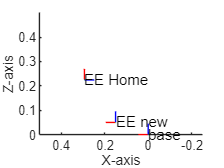

success = logical
   1


i = 3

Tsb =     1.0000         0    0.0000    0.1500
         0    1.0000         0         0
   -0.0000         0    1.0000    0.0500
         0         0         0    1.0000


ans =          0
    2.3180
   10.6396
   77.0424


thetaListdeg =          0
    2.3180
   10.6396
   77.0424



T = [   [1, 0, 0, .15000]; 
        [0, 1, 0, 0]; 
        [0, 0, 1, 0.05000]; 
        [0, 0, 0, 1]];
T2= [   [0, 0, -1, .15000]; 
        [0, 1, 0, 0]; 
        [1, 0, 0, 0.05000]; 
        [0, 0, 0, 1]];
% thetalist0 = [0; deg2rad(90); deg2rad(80); deg2rad(-170);];

thetalist0 = [ deg2rad([0    0    10    90]')];
thetalist02= [deg2rad([0    90    90    180]')];
eomg = 0.000001;
ev = 0.000001;
thetaListdeg=rad2deg(IKinSpace(Slist,M,T,thetalist0,eomg,ev))

thetaListdeg2=rad2deg(IKinSpace(Slist,M,T2,thetalist02,eomg,ev))

success = logical
   1


i = 3

Tsb =          0         0   -1.0000    0.1500
         0    1.0000         0         0
    1.0000         0         0    0.0500
         0         0         0    1.0000


ans =          0
   91.7926
   79.7030
  188.5043


thetaListdeg2 =          0
   91.7926
   79.7030
  188.5043


d)

I=[ 1 0 0
    0 1 0
    0 0 1];
mlist=zeros(4,4,5);
mp=zeros(3,1,4);
% R=zeros(3,3,5)
mp(:,:,1)=[0;0.00057;0.07545];

mp(:,:,2)=[0.00486;-0.00025;.10353+.05835+.03808];
% R(:,1,1)=unitVector(mp(:,:,2)-mp(:,:,1))
% R(:,2,1)=I(1:3,2)-(I(1:3,2).*R(:,1,1)).*R(:,1,1)
% R(:,3,1)=cross(R(:,1,1),R(:,2,1))
% 
% mlist(:,:,1)=[R(:,:,1) mp(:,:,1); 0 0 0 1];
mlist(:,:,1)=[I mp(:,:,1); 0 0 0 1];
m02=[1 0 0 .00486
    0 1 0 -.00025
    0 0 1 .10353+.05835+.03808
    0 0 0 1];
% mlist(:,:,2)=[I transpose(R)*(mp(:,:,2)-mp(:,:,1)); 0 0 0 1];
mlist(:,:,2)=[I (mp(:,:,2)-mp(:,:,1)); 0 0 0 1];
% R=[ 0 0 1
%     0 1 0
%     -1 0 0
%     ]


% mlist(:,:,2)=[R (m02(1:3,4)-mlist(1:3,4,1)); 0 0 0 1];
m03=[I [ 0.09370+0.02400; -0.00001; 0.00064+0.12800+0.05825+0.03808;]; 0 0 0 1];
% mlist(:,:,3)=[I R*(m03(1:3,4)-m02(1:3,4)); 0 0 0 1];
mlist(:,:,3)=[I (m03(1:3,4)-m02(1:3,4)); 0 0 0 1];
m04=[I [0.06424+0.12400+0.02400; -0.00001; 0.00549+0.12800+0.05825+0.03808]; 0 0 0 1];
% mlist(:,:,4)=[I R*(m04(1:3,4)-m03(1:3,4)); 0 0 0 1];
mlist(:,:,4)=[I (m04(1:3,4)-m03(1:3,4)); 0 0 0 1];
% mlist(:,:,5)=[M(1:3,1:3) R*(M(1:3,4)-m04(1:3,4)); 0 0 0 1]
mlist(:,:,5)=[M(1:3,1:3) (M(1:3,4)-m04(1:3,4)); 0 0 0 1]

mlist = mlist(:,:,1) =

    1.0000         0         0         0
         0    1.0000         0    0.0006
         0         0    1.0000    0.0755
         0         0         0    1.0000


mlist(:,:,2) =

    1.0000         0         0    0.0049
         0    1.0000         0   -0.0008
         0         0    1.0000    0.1245
         0         0         0    1.0000


mlist(:,:,3) =

    1.0000         0         0    0.1128
         0    1.0000         0    0.0002
         0         0    1.0000    0.0250
         0         0         0    1.0000


mlist(:,:,4) =

    1.0000         0         0    0.0945
         0    1.0000         0         0
         0         0    1.0000    0.0048
         0         0         0    1.0000


mlist(:,:,5) =

         0         0   -1.0000    0.0812
         0    1.0000         0    0.0000
    1.0000         0         0   -0.0055
         0         0         0    1.0000


TestHome=eye(4);
for n=1:size(mlist,3)
    TestHome=TestHome*mlist(:,:,n);
end
disp('Mlist->Home')

Mlist->Home


disp(TestHome)

         0         0   -1.0000    0.2934
         0    1.0000         0    0.0000
    1.0000         0         0    0.2243
         0         0         0    1.0000



disp('Home')

Home


disp(M)

         0         0   -1.0000    0.2934
         0    1.0000         0         0
    1.0000         0         0    0.2243
         0         0         0    1.0000



format short
disp('mlist')

mlist


disp(mlist)


(:,:,1) =

    1.0000         0         0         0
         0    1.0000         0    0.0006
         0         0    1.0000    0.0755
         0         0         0    1.0000


(:,:,2) =

    1.0000         0         0    0.0049
         0    1.0000         0   -0.0008
         0         0    1.0000    0.1245
         0         0         0    1.0000


(:,:,3) =

    1.0000         0         0    0.1128
         0    1.0000         0    0.0002
         0         0    1.0000    0.0250
         0         0         0    1.0000


(:,:,4) =

    1.0000         0         0    0.0945
         0    1.0000         0         0
         0         0    1.0000    0.0048
         0         0         0    1.0000


(:,:,5) =

         0         0   -1.0000    0.0812
         0    1.0000         0    0.0000
    1.0000         0         0   -0.0055
         0         0         0    1.0000



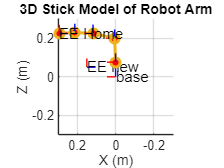

Model(mlist);

re arrange

% % Inputs
% T_list = mlist; % Original dependent transformations
% R_adjust_list = {R0, R1, R2, R3}; % Adjustment rotations for each frame
% 
% % Initialize adjusted transformations
% n = length(T_list);
% T_new_list = cell(1, n);
% 
% % Adjust the first transformation
% T_new_list{1} = [R_adjust_list{1} * T_list{1}(1:3, 1:3), R_adjust_list{1} * T_list{1}(1:3, 4); 0 0 0 1];
% 
% % Propagate adjustments through the chain
% for i = 2:n
%     % Adjust the local transformation
%     T_local = T_list{i};
%     R_adjust = R_adjust_list{i};
%     R_new = R_adjust * T_local(1:3, 1:3);
%     t_new = R_adjust * T_local(1:3, 4);
%     T_new = [R_new, t_new; 0 0 0 1];
% 
%     % Multiply with the preceding adjusted transformations
%     T_new_list{i} = T_new_list{i-1} * T_new;
% end


e)

Glist=zeros(6,6,4);
ro2b=[  0 1 0 
        0 0 1 
        1 0 0 ];
% test=ihalf2ifull([1 2 3], [4 5 6])
n=6;
Glist(:,:,1)=sltoml([54860 791 0; 791 25604 0; 0 0 56910],114,ro2b,n);
Glist(:,:,2)=sltoml([224228.29 2135.31 30913.63; 2135.31 229056.61 5289.51; 30913.63 5289.51 54250.9],140,I,n);
Glist(:,:,3)=sltoml(ihalf2ifull([27859.41,140025.95,150406.23],[4186.08,-7162.89,-735.53]),118,I,n);
Glist(:,:,4)=sltoml(ihalf2ifull([172924.13 199140.18 267630.72],[-131.89 -23187.17 48.11]),218,I,n);

% Glist(:,:,1)=sltoml(ihalf2ifull([54860 25604 56910],zeros(3,1)),114,ro2b,n);
% Glist(:,:,2)=sltoml(ihalf2ifull([224228.29 229056.61 54250.9],zeros(3,1)),140,I,n);
% Glist(:,:,3)=sltoml(ihalf2ifull([27859.41,140025.95,150406.23],[zeros(3,1)]),118,I,n);
% Glist(:,:,4)=sltoml(ihalf2ifull([172924.13 199140.18 267630.72],[zeros(3,1)]),218,I,n);
format shorte
disp('glist')

glist


disp(Glist)


(:,:,1) =

   5.6910e-02            0            0            0            0            0
            0   5.4860e-02   7.9100e-04            0            0            0
            0   7.9100e-04   2.5604e-02            0            0            0
            0            0            0   1.1400e-01            0            0
            0            0            0            0   1.1400e-01            0
            0            0            0            0            0   1.1400e-01


(:,:,2) =

   2.2423e-01   2.1353e-03   3.0914e-02            0            0            0
   2.1353e-03   2.2906e-01   5.2895e-03            0            0            0
   3.0914e-02   5.2895e-03   5.4251e-02            0            0            0
            0            0            0   1.4000e-01            0            0
            0            0            0            0   1.4000e-01            0
            0            0            0            0            0   1.4000e-01


(:,:,3) =

   2.7859e-02 

f)

format short
disp('test home')

test home


disp(InverseDynamics(zeros(4,1),zeros(4,1),zeros(4,1),[0; 0; -9.8],[0;0;0;0;0;0],mlist,Glist,Slist))

         0
   -0.5962
   -0.5105
   -0.1372



disp('HW problem normal')

HW problem normal


disp(InverseDynamics(deg2rad(thetaListdeg),zeros(4,1),zeros(4,1),[0; 0; -9.8],[0;0;0;0;0;10],mlist,Glist,Slist))

   -0.0000
   -1.9841
   -1.5841
   -0.0117



disp('HW problem turtle')

HW problem turtle


disp(InverseDynamics(deg2rad(thetaListdeg2),zeros(4,1),zeros(4,1),[0; 0; -9.8],[0;0;0;10;0;0],mlist,Glist,Slist))

   -0.0000
   -1.8289
    0.0037
   -1.5917



trouble

% out=zeros(4,9);
% for i=1:9
%     Glist(:,:,1)=sltoml([54860 791 0; 791 25604 0; 0 0 56910],114,ro2b,i);
% Glist(:,:,2)=sltoml([224228.29 2135.31 30913.63; 2135.31 229056.61 5289.51; 30913.63 5289.51 54250.9],140,I,i);
% Glist(:,:,3)=sltoml(ihalf2ifull([27859.41,140025.95,150406.23],[4186.08,-7162.89,-735.53]),118,I,i);
% Glist(:,:,4)=sltoml(ihalf2ifull([172924.13 199140.18 267630.72],[-131.89 -23187.17 48.11]),218,I,i);
%     out(:,i)=ForwardDynamics(zeros(4,1),zeros(4,1),zeros(4,1),[0; 0; -9.8],[0;0;0;0;0;0],mlist,Glist,Slist);
% end
% figure;
% plot([1:9],out)
% hold on
% yline([0 .6 .5 .14])
% format long
% disp(out)
% xlim([1,9])
% ylim([-1,1])

func


% function out=ihalf2ifull(idia, icorner)
%     out=[idia(1) icorner(1) icorner(2); icorner(1) idia(2) icorner(3); icorner(2) icorner(3) idia(3)];
% end
%convert rotational inertia matrix and mass from matlab cordinate system
%and mm/g to spatial inertial matrix in problem cordinate system 
% function out=sltoml(moiAtocs,mass,ro2b,n)
%     outR=transpose(ro2b)*moiAtocs*ro2b;
%     outR=outR/(10^n);
%     % outR=outR*10^-9;
%     outP=(mass/1000)*[1 0 0;0 1 0; 0 0 1];
%     out=[outR zeros(3,3); zeros(3,3) outP];
% end
% function uv=unitVector(vector)
%     uv=vector/sqrt(sum(vector.^2))
% end
